load("MATRIX_DBS.mat")
nside = length(MATRIX_DBS.fs);

TotalSignalONDBS = cell(nside,1);
TotalThrONDBS = cell(nside,1);
TotalFreStdONDBS = cell(nside,1);

TotalSignalOFFDBS = cell(nside,1);
TotalThrOFFDBS = cell(nside,1);
TotalFreStdOFFDBS = cell(nside,1);

meanWin = 0.6;
%low beta
layerNum = 6;
basis = 'sym8';
frequencyBand = 4;
filterPara.fp_highpass=12;
filterPara.fp_lowpass=24;

for iside= 1:nside 
    fs=MATRIX_DBS.fs(iside);
    fsResample = 384;
    disp(['Sub: ' num2str(iside)]);
    %% Signal Base
    signal_base=MATRIX_DBS.signal_base{iside};
    signal_DBS=MATRIX_DBS.signal_dbs{iside};
    
    signal_base_Resample = resample(signal_base,fsResample,fs);
    signal_DBS_Resample = resample(signal_DBS,fsResample,fs);

    %cut signal to swt
    n  = fix(length(signal_base_Resample)/(2^layerNum));
    signal_base_Resample = signal_base_Resample(1:n*(2^layerNum));

    n  = fix(length(signal_DBS_Resample)/(2^layerNum));
    signal_DBS_Resample = signal_DBS_Resample(1:n*(2^layerNum));

    timeOn = (1:1:length(signal_DBS_Resample))/fsResample;
    timeOff = (1:1:length(signal_base_Resample))/fsResample;
    [~,CoffOn,ThrOn,PatternOn] =  SynEstimate(timeOn,signal_DBS_Resample',fsResample,layerNum,basis,frequencyBand);
    [~,CoffOff,ThrOff,PatternOff] =  SynEstimate(timeOff,signal_base_Resample',fsResample,layerNum,basis,frequencyBand);
    
    %%把带通滤波器写成函数放在这里
    [bpOn,~] = Bandpass(filterPara,fsResample,signal_DBS_Resample',timeOn);
    powerOn = smoothdata(abs(bpOn),"movmedian",round(meanWin*fsResample));

    [bpOff,~] = Bandpass(filterPara,fsResample,signal_base_Resample',timeOff);
    powerOff = smoothdata(abs(bpOff),"movmedian",round(meanWin*fsResample));

    % 使用buffer函数创建滑动窗口
    insFreq = fsResample/(2*pi)*diff(unwrap(angle(hilbert(bpOn))))';
    windowed_data = buffer(insFreq, round(meanWin*fsResample), round(meanWin*fsResample)-1, 'nodelay');
    % 计算每个窗口的方差
    FreStdOn = var(windowed_data);

    % 使用buffer函数创建滑动窗口
    insFreq = fsResample/(2*pi)*diff(unwrap(angle(hilbert(bpOff))))';
    windowed_data = buffer(insFreq, round(meanWin*fsResample), round(meanWin*fsResample)-1, 'nodelay');
    % 计算每个窗口的方差
    FreStdOff = var(windowed_data);

    TotalSignalONDBS(iside) = {powerOn};
    TotalThrONDBS(iside) = {ThrOn};
    TotalFreStdONDBS(iside) = {FreStdOn};

    TotalSignalOFFDBS(iside) = {powerOff};
    TotalThrOFFDBS(iside) = {ThrOff};
    TotalFreStdOFFDBS(iside) = {FreStdOff};

end

Sub: 1
Sub: 2
Sub: 3
Sub: 4
Sub: 5
Sub: 6
Sub: 7
Sub: 8
Sub: 9
Sub: 10
Sub: 11
Sub: 12
Sub: 13
Sub: 14
Sub: 15
Sub: 16
Sub: 17
Sub: 18
Sub: 19
Sub: 20
Sub: 21
Sub: 22
Sub: 23
Sub: 24
Sub: 25
Sub: 26


ThrKLDBS = zeros(nside,1);
ThrONEntropyDBS = zeros(nside,1);
ThrOFFEntropyDBS = zeros(nside,1);

for iside = 1:nside
    ThrON  = cell2mat(TotalThrONDBS(iside));
    ThrOFF  = cell2mat(TotalThrOFFDBS(iside));
        ThrOff = ThrOFF;
        ThrOn = ThrON;
        Thr = [ThrOff ThrOn];

        minEdge = min([min(ThrON) min(ThrOFF)]);
        maxEdge = max([max(ThrON) max(ThrOFF)]);
        edges = [minEdge:(maxEdge-minEdge)/20:maxEdge];
        
        [NOff,a] = histcounts(ThrOff,edges, 'Normalization', 'probability');
        [NOn,a ] = histcounts(ThrOn,edges, 'Normalization', 'probability');
        NOff(NOff == 0) = eps;
        NOn(NOn == 0) = eps;
        
        ThrKLDBS(iside) = sum(NOff .* log2(NOff ./ NOn), 'omitnan');

        ThrONEntropyDBS(iside) = -sum(NOn .* log2(NOn));
        ThrOFFEntropyDBS(iside) = -sum(NOff .* log2(NOff));

end

%[h,p] = ttest(ThrOFFEntropyDBS,ThrONEntropyDBS)
[h,p] = ttest(ThrKLDBS)

h = 1

p = 0.0019

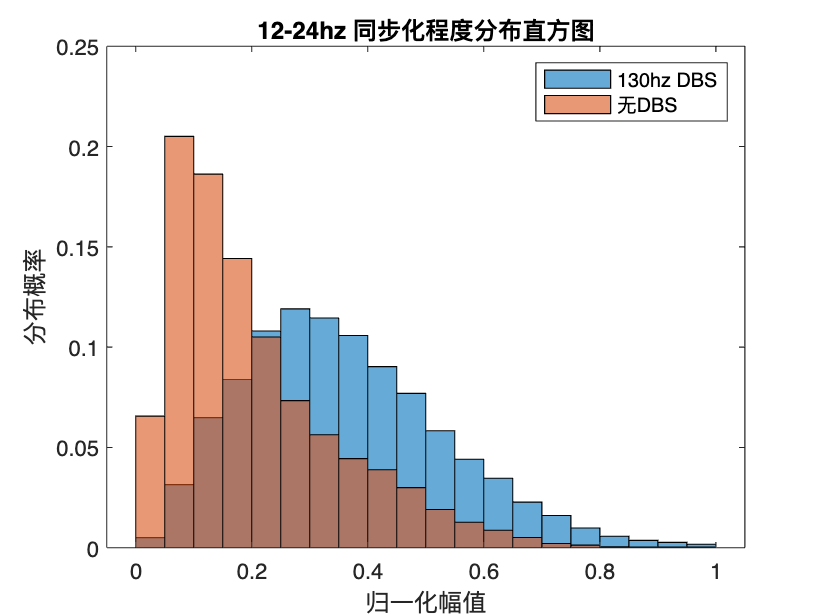


ThrlistOff = [];
ThrlistOn = [];

for iside = 1:nside
    ThrON  = cell2mat(TotalThrONDBS(iside));
    ThrOFF  = cell2mat(TotalThrOFFDBS(iside));
    ThrOff = ThrOFF;
    ThrOn = ThrON;
    Thr = [ThrOff ThrOn];
    NormThr = normalize(Thr,'range');
    NormThrOff = NormThr(1:length(ThrOff));
    NormThrOn = NormThr(length(ThrOff)+1:end);
    ThrlistOff = [ThrlistOff NormThrOff];
    ThrlistOn= [ThrlistOn NormThrOn];
end

figure;
edges = [0:0.05:1];
h1L = histogram(ThrlistOff,edges,'Normalization','probability');
hold on
h2L = histogram(ThrlistOn,edges,'Normalization','probability');
title('12-24hz 同步化程度分布直方图');
xlabel('归一化幅值');
ylabel('分布概率');
legend('130hz DBS','无DBS');

SignalKLDBS = zeros(nside,1);
SignalONEntropyDBS = zeros(nside,1);
SignalOFFEntropyDBS = zeros(nside,1);

for iside = 1:nside
    SignalON  = cell2mat(TotalSignalONDBS(iside));
    SignalOFF  = cell2mat(TotalSignalOFFDBS(iside));
    for layer = 1:LayerNum-1
        SignalOff = SignalOFF';
        SignalOn = SignalON';
        Signal = [SignalOff SignalOn];

        minEdge = min([min(SignalON) min(SignalOFF)]);
        maxEdge = max([max(SignalON) max(SignalOFF)]);
        edges = [minEdge:(maxEdge-minEdge)/20:maxEdge];
        
        [NOff,a] = histcounts(SignalOff,edges, 'Normalization', 'probability');
        [NOn,a ] = histcounts(SignalOn,edges, 'Normalization', 'probability');
        NOff(NOff == 0) = eps;
        NOn(NOn == 0) = eps;
        SignalKLDBS(iside) = sum(NOff .* log2(NOff ./ NOn), 'omitnan');

        SignalONEntropyDBS(iside) = -sum(NOn .* log2(NOn));
        SignalOFFEntropyDBS(iside) = -sum(NOff .* log2(NOff));

        %}
    end
end

[h,p] = ttest(SignalOFFEntropyDBS ,SignalONEntropyDBS)

h = 1

p = 8.7281e-05

[h,p] = ttest(SignalKLDBS)

h = 1

p = 0.0043

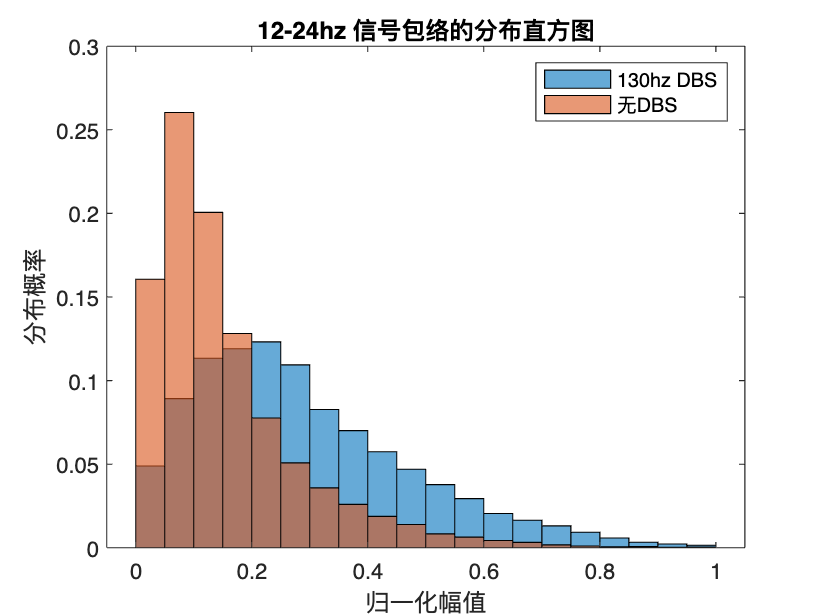

SignallistOff = [];
SignallistOn = [];
edges = [0:0.05:1];

for iside = 1:nside
    SignalON  = cell2mat(TotalSignalONDBS(iside));
    SignalOFF  = cell2mat(TotalSignalOFFDBS(iside));
    SignalOff = SignalOFF';
    SignalOn = SignalON';
    Signal = [SignalOff SignalOn];
    NormSignal = normalize(Signal,'range');
    NormSignalOff = NormSignal(1:length(SignalOff));
    NormSignalOn = NormSignal(length(SignalOff)+1:end);
    SignallistOff = [SignallistOff NormSignalOff];
    SignallistOn= [SignallistOn NormSignalOn];
end

figure;
h1L = histogram(SignallistOff,edges,'Normalization','probability');
hold on
h2L = histogram(SignallistOn,edges,'Normalization','probability');
title('12-24hz 信号包络的分布直方图');
xlabel('归一化幅值');
ylabel('分布概率');
legend('130hz DBS','无DBS');
fig = gcf;
saveas(fig, filename, filetype);

FreStdKLDBS = zeros(nside,1);

for iside = 1:nside
    FreStdON  = 1./cell2mat(TotalFreStdONDBS(iside));
    FreStdOFF  = 1./cell2mat(TotalFreStdOFFDBS(iside));
    FreStd = [FreStdOFF FreStdON];
    %FreON(iside) = FreStdON;
    %FreOFF(iside) = FreStdOFF;
    
    minEdge = min([min(FreStdON) min(FreStdOFF)]);
    maxEdge = max([max(FreStdON) max(FreStdOFF)]);
    edges = [minEdge:(maxEdge-minEdge)/20:maxEdge];
    [NOff,a] = histcounts(FreStdOFF,edges, 'Normalization', 'probability');
    [NOn,a ] = histcounts(FreStdON,edges, 'Normalization', 'probability');
    NOff(NOff == 0) = eps;
    NOn(NOn == 0) = eps;
    FreStdKLDBS(iside)= sum(NOff .* log2(NOff ./ NOn), 'omitnan');
    
end


[h,p] = ttest(FreStdKLDBS)

h = 0

p = 0.1526

%{

LayerNum = 6;
ThrMeanONDBS = zeros(nside,LayerNum-1);
ThrMeanOFFDBS = zeros(nside,LayerNum-1);
edges = [0:0.05:1];
nside = 26;
for iside = 1:nside
    ThrON  = cell2mat(TotalThrONDBS(iside));
    ThrOFF  = cell2mat(TotalThrOFFDBS(iside));
    for layer = 2:LayerNum
        ThrOff = ThrOFF(layer,:);
        ThrOn = ThrON(layer,:);
        Thr = [ThrOff ThrOn];
        NormThr = normalize(Thr,'range');
        NormThrOff = NormThr(1:length(ThrOff));
        NormThrOn = NormThr(length(ThrOff)+1:end);
        ThrMeanONDBS(iside,layer-1) = mean(NormThrOn);
        ThrMeanOFFDBS(iside,layer-1) = mean(NormThrOff);
    end
end

SignalMeanONDBS = zeros(nside,LayerNum-1);
SignalMeanOFFDBS = zeros(nside,LayerNum-1);

LayerNum = 5;
for iside = 1:nside
    SignalON  = cell2mat(TotalSignalONDBS(iside));
    SignalOFF  = cell2mat(TotalSignalOFFDBS(iside));
    for layer = 1:LayerNum
        SignalOff = SignalOFF(layer,:);
        SignalOn = SignalON(layer,:);
        Signal = [SignalOff SignalOn];
        NormSignal = normalize(Signal,'range');
        NormSignalOff = NormSignal(1:length(SignalOff));
        NormSignalOn = NormSignal(length(SignalOff)+1:end);
        SignalMeanONDBS(iside,layer) = mean(NormSignalOn);
        SignalMeanOFFDBS(iside,layer) = mean(NormSignalOff);
    end
end

[h,p] = ttest(ThrMeanOFFDBS,ThrMeanONDBS)

h =      1     0     1     1     0


p =     0.0000    0.9461    0.0000    0.0353    0.9063


[h,p] = ttest(SignalMeanOFFDBS,SignalMeanONDBS)

h =      0     1     1     0     0


p =     0.0695    0.0000    0.0022    0.1459    0.9334


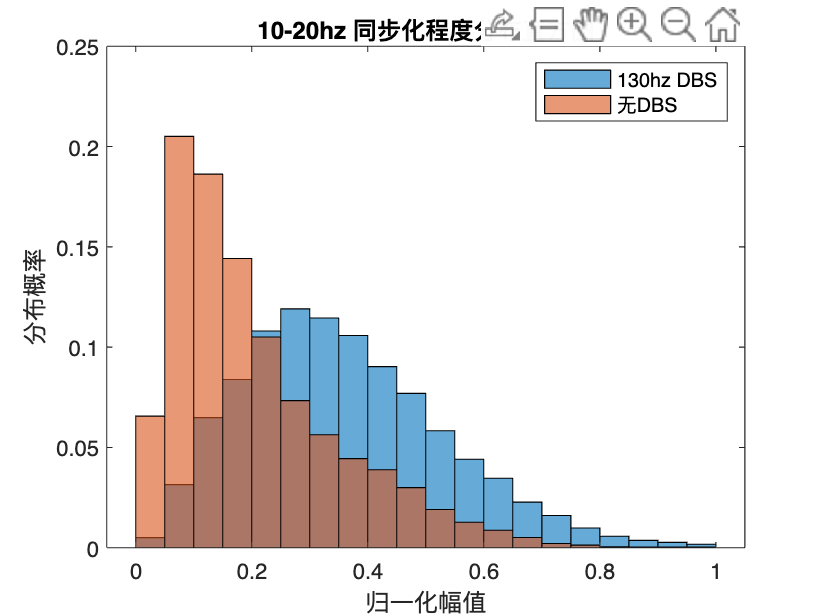

ThrlistOff = [];
ThrlistOn = [];
filename = '10-20Thr.png';
filetype = 'png';

for iside = 1:nside
    ThrON  = cell2mat(TotalThrONDBS(iside));
    ThrOFF  = cell2mat(TotalThrOFFDBS(iside));
    ThrOff = ThrOFF;
    ThrOn = ThrON;
    Thr = [ThrOff ThrOn];
    NormThr = normalize(Thr,'range');
    NormThrOff = NormThr(1:length(ThrOff));
    NormThrOn = NormThr(length(ThrOff)+1:end);
    ThrlistOff = [ThrlistOff NormThrOff];
    ThrlistOn= [ThrlistOn NormThrOn];
end

figure;
edges = [0:0.05:1];
h1L = histogram(ThrlistOff,edges,'Normalization','probability');
hold on
h2L = histogram(ThrlistOn,edges,'Normalization','probability');
title('10-20hz 同步化程度分布直方图');
xlabel('归一化幅值');
ylabel('分布概率');
legend('130hz DBS','无DBS');
fig = gcf;
saveas(fig, filename, filetype);


[NOff,a] = histcounts(ThrlistOff,edges, 'Normalization', 'probability');
[NOn,a ] = histcounts(ThrlistOn,edges, 'Normalization', 'probability');
NOff(NOff == 0) = eps;
NOn(NOn == 0) = eps;
ThrKLTotal = sum(NOff .* log2(NOff ./ NOn), 'omitnan')

ThrKLTotal = 0.6938

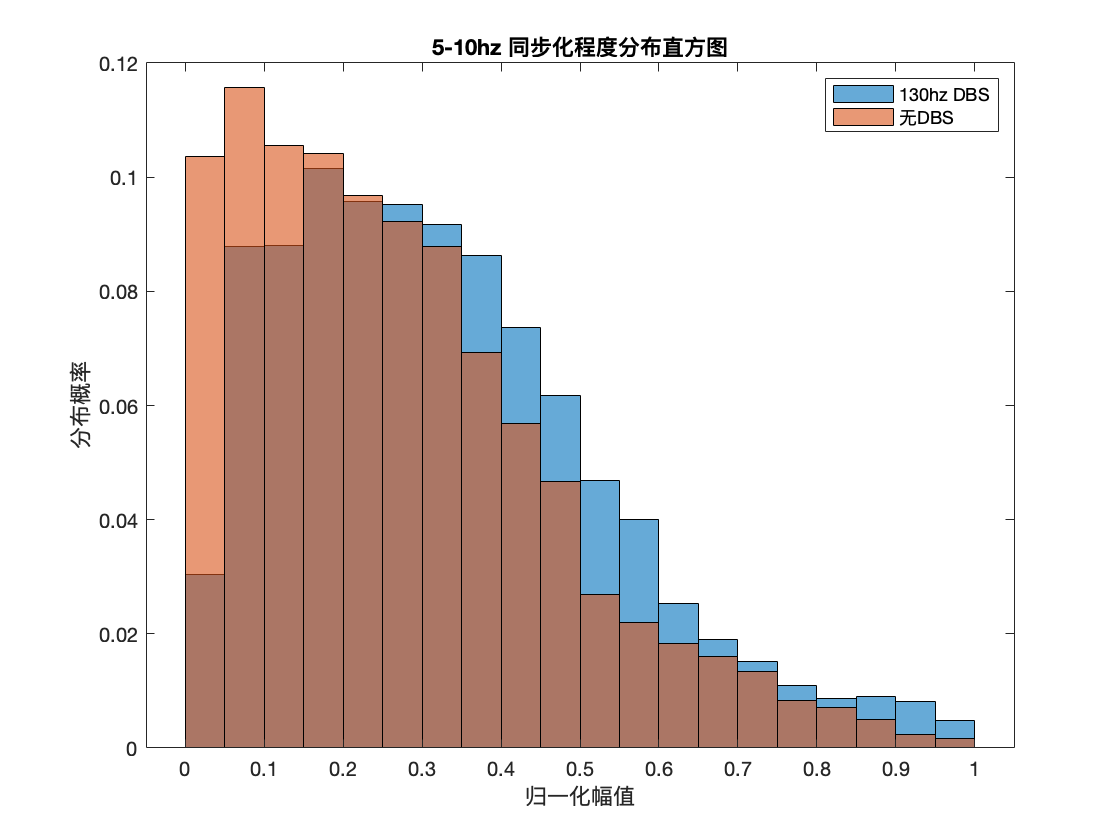

ThrlistOff = [];
ThrlistOn = [];
filename = '5-10Thr.png';
filetype = 'png';

for iside = 1:nside
    ThrON  = cell2mat(TotalThrONDBS(iside));
    ThrOFF  = cell2mat(TotalThrOFFDBS(iside));
    ThrOff = ThrOFF(5,:);
    ThrOn = ThrON(5,:);
    Thr = [ThrOff ThrOn];
    NormThr = normalize(Thr,'range');
    NormThrOff = NormThr(1:length(ThrOff));
    NormThrOn = NormThr(length(ThrOff)+1:end);
    ThrlistOff = [ThrlistOff NormThrOff];
    ThrlistOn= [ThrlistOn NormThrOn];
end

figure;
edges = [0:0.05:1];
h1L = histogram(ThrlistOff,edges,'Normalization','probability');
hold on
h2L = histogram(ThrlistOn,edges,'Normalization','probability');
title('5-10hz 同步化程度分布直方图');
xlabel('归一化幅值');
ylabel('分布概率');
legend('130hz DBS','无DBS');
fig = gcf;
saveas(fig, filename, filetype);

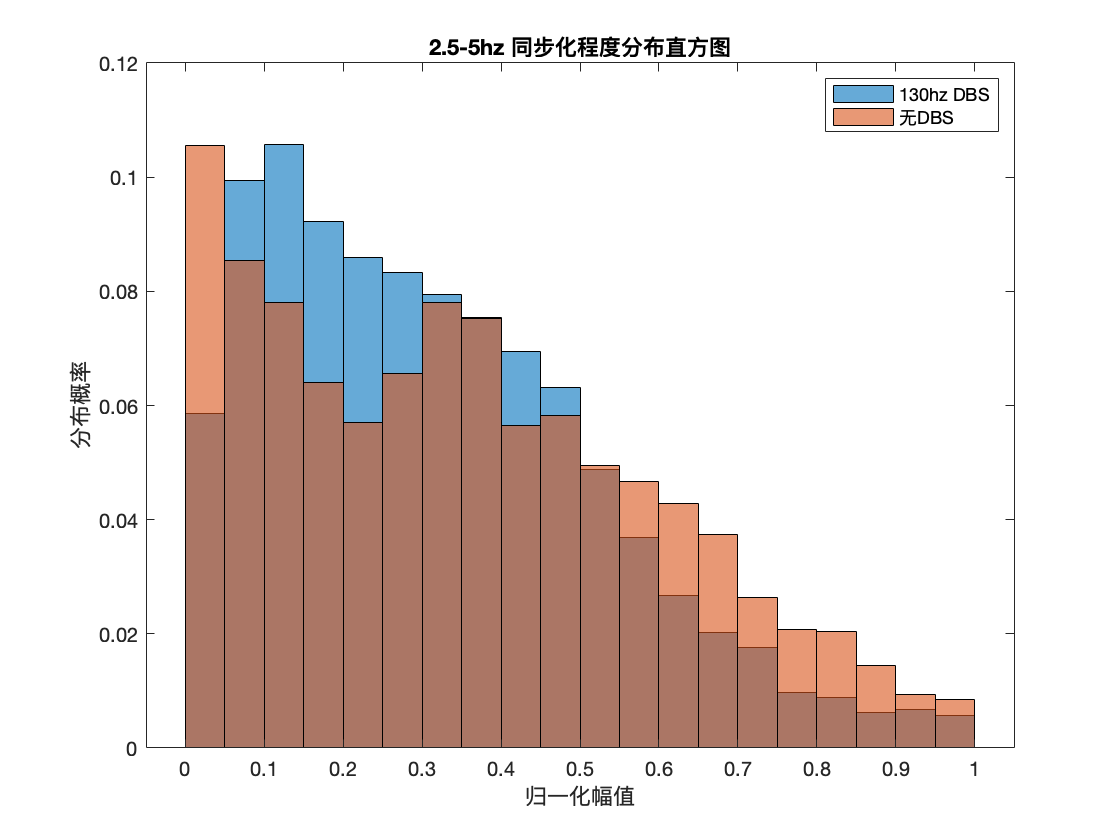

ThrlistOff = [];
ThrlistOn = [];
filename = '2.5-5Thr.png';
filetype = 'png';

for iside = 1:nside
    ThrON  = cell2mat(TotalThrONDBS(iside));
    ThrOFF  = cell2mat(TotalThrOFFDBS(iside));
    ThrOff = ThrOFF(6,:);
    ThrOn = ThrON(6,:);
    Thr = [ThrOff ThrOn];
    NormThr = normalize(Thr,'range');
    NormThrOff = NormThr(1:length(ThrOff));
    NormThrOn = NormThr(length(ThrOff)+1:end);
    ThrlistOff = [ThrlistOff NormThrOff];
    ThrlistOn= [ThrlistOn NormThrOn];
end

figure;
edges = [0:0.05:1];
h1L = histogram(ThrlistOff,edges,'Normalization','probability');
hold on
h2L = histogram(ThrlistOn,edges,'Normalization','probability');
title('2.5-5hz 同步化程度分布直方图');
xlabel('归一化幅值');
ylabel('分布概率');
legend('130hz DBS','无DBS');
fig = gcf;
saveas(fig, filename, filetype);

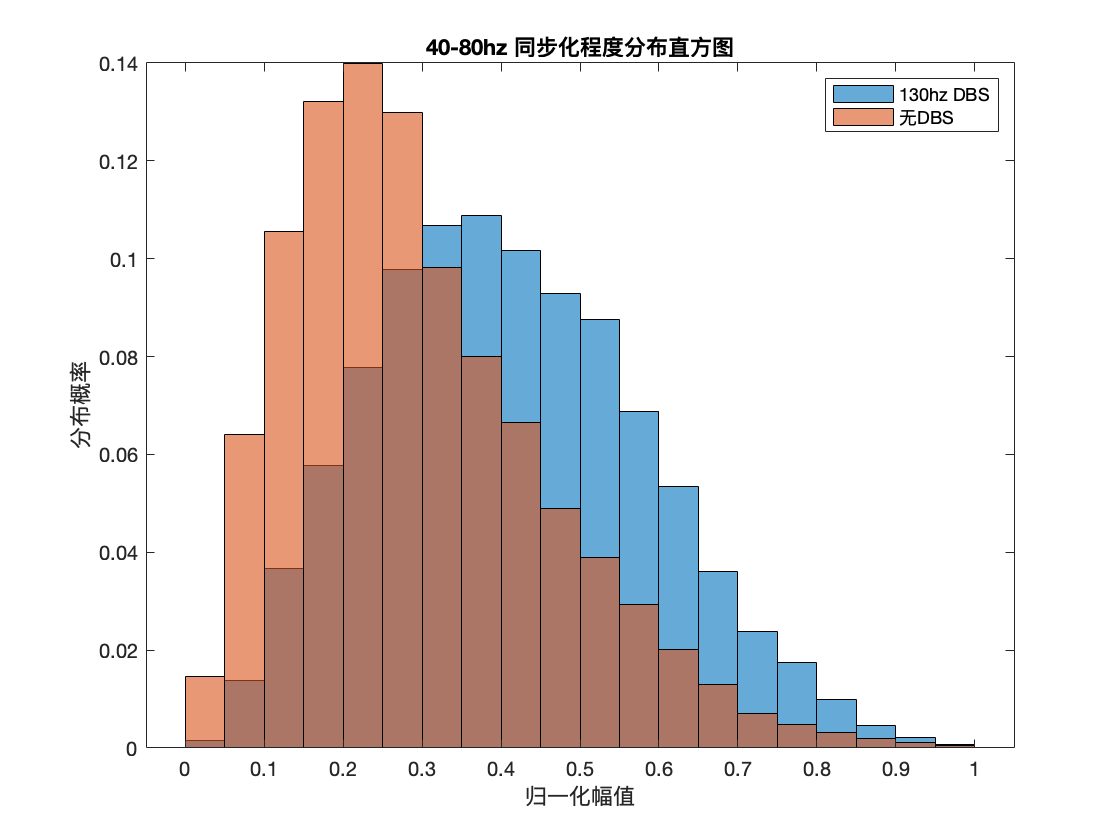

ThrlistOff = [];
ThrlistOn = [];
filename = '40-80Thr.png';
filetype = 'png';

for iside = 1:nside
    ThrON  = cell2mat(TotalThrONDBS(iside));
    ThrOFF  = cell2mat(TotalThrOFFDBS(iside));
    ThrOff = ThrOFF(2,:);
    ThrOn = ThrON(2,:);
    Thr = [ThrOff ThrOn];
    NormThr = normalize(Thr,'range');
    NormThrOff = NormThr(1:length(ThrOff));
    NormThrOn = NormThr(length(ThrOff)+1:end);
    ThrlistOff = [ThrlistOff NormThrOff];
    ThrlistOn= [ThrlistOn NormThrOn];
end

figure;
edges = [0:0.05:1];
h1L = histogram(ThrlistOff,edges,'Normalization','probability');
hold on
h2L = histogram(ThrlistOn,edges,'Normalization','probability');
title('40-80hz 同步化程度分布直方图');
xlabel('归一化幅值');
ylabel('分布概率');
legend('130hz DBS','无DBS');
fig = gcf;
saveas(fig, filename, filetype);

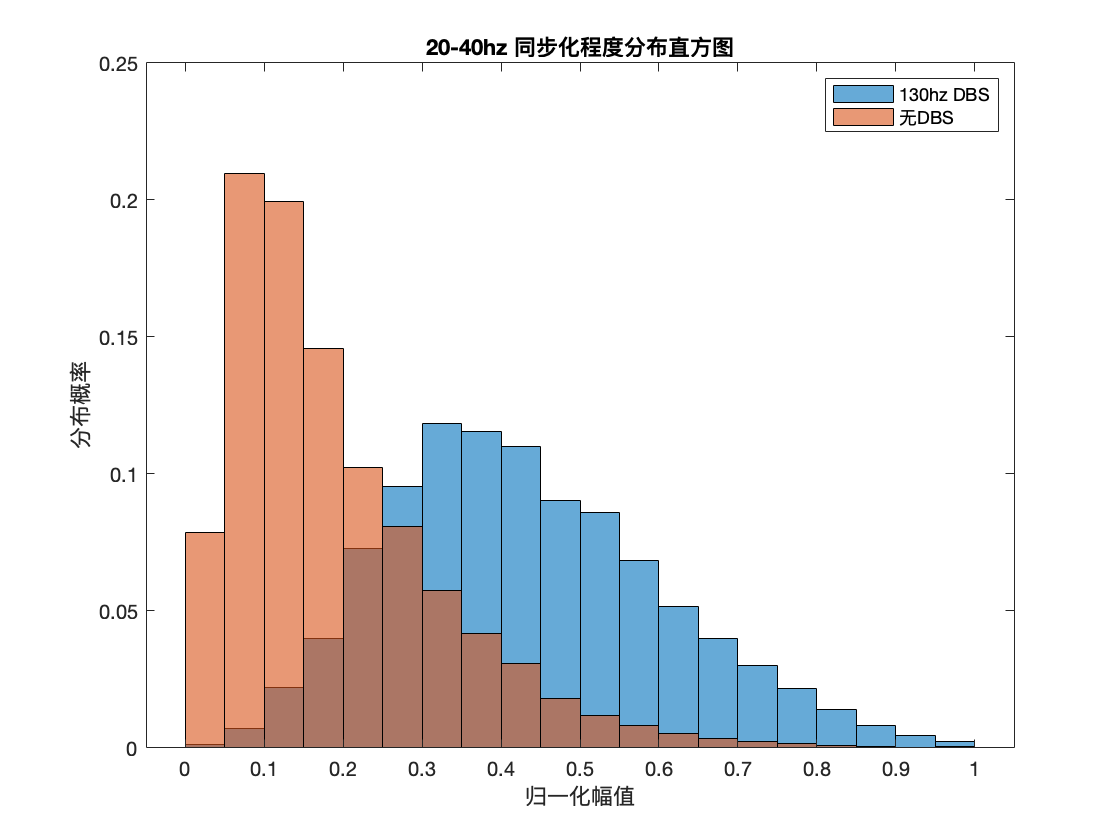

ThrlistOff = [];
ThrlistOn = [];
filename = '20-40Thr.png';
filetype = 'png';


for iside = 1:nside
    ThrON  = cell2mat(TotalThrONDBS(iside));
    ThrOFF  = cell2mat(TotalThrOFFDBS(iside));
    ThrOff = ThrOFF(3,:);
    ThrOn = ThrON(3,:);
    Thr = [ThrOff ThrOn];
    NormThr = normalize(Thr,'range');
    NormThrOff = NormThr(1:length(ThrOff));
    NormThrOn = NormThr(length(ThrOff)+1:end);
    ThrlistOff = [ThrlistOff NormThrOff];
    ThrlistOn= [ThrlistOn NormThrOn];
end

figure;
edges = [0:0.05:1];
h1L = histogram(ThrlistOff,edges,'Normalization','probability');
hold on
h2L = histogram(ThrlistOn,edges,'Normalization','probability');
title('20-40hz 同步化程度分布直方图');
xlabel('归一化幅值');
ylabel('分布概率');
legend('130hz DBS','无DBS');
fig = gcf;
saveas(fig, filename, filetype);
fig = gcf;
saveas(fig, filename, filetype);

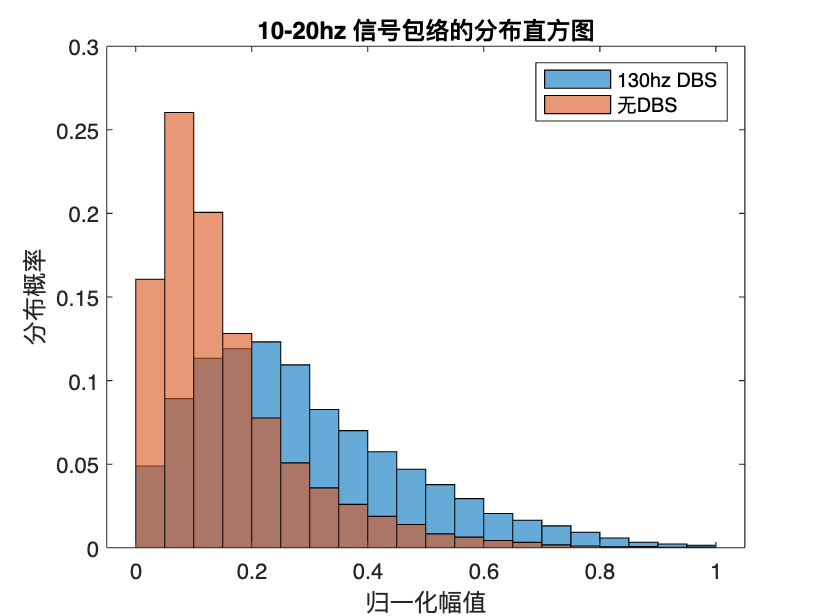

SignallistOff = [];
SignallistOn = [];
edges = [0:0.05:1];
filename = '10-20Signal.png';
filetype = 'png';

for iside = 1:nside
    SignalON  = cell2mat(TotalSignalONDBS(iside));
    SignalOFF  = cell2mat(TotalSignalOFFDBS(iside));
    SignalOff = SignalOFF';
    SignalOn = SignalON';
    Signal = [SignalOff SignalOn];
    NormSignal = normalize(Signal,'range');
    NormSignalOff = NormSignal(1:length(SignalOff));
    NormSignalOn = NormSignal(length(SignalOff)+1:end);
    SignallistOff = [SignallistOff NormSignalOff];
    SignallistOn= [SignallistOn NormSignalOn];
end

figure;
h1L = histogram(SignallistOff,edges,'Normalization','probability');
hold on
h2L = histogram(SignallistOn,edges,'Normalization','probability');
title('10-20hz 信号包络的分布直方图');
xlabel('归一化幅值');
ylabel('分布概率');
legend('130hz DBS','无DBS');
fig = gcf;
saveas(fig, filename, filetype);



[NOff,a] = histcounts(SignallistOff,edges, 'Normalization', 'probability');
[NOn,a ] = histcounts(SignallistOn,edges, 'Normalization', 'probability');
NOff(NOff == 0) = eps;
NOn(NOn == 0) = eps;
SignalKLTotal = sum(NOff .* log2(NOff ./ NOn), 'omitnan')

SignalKLTotal = 0.5849

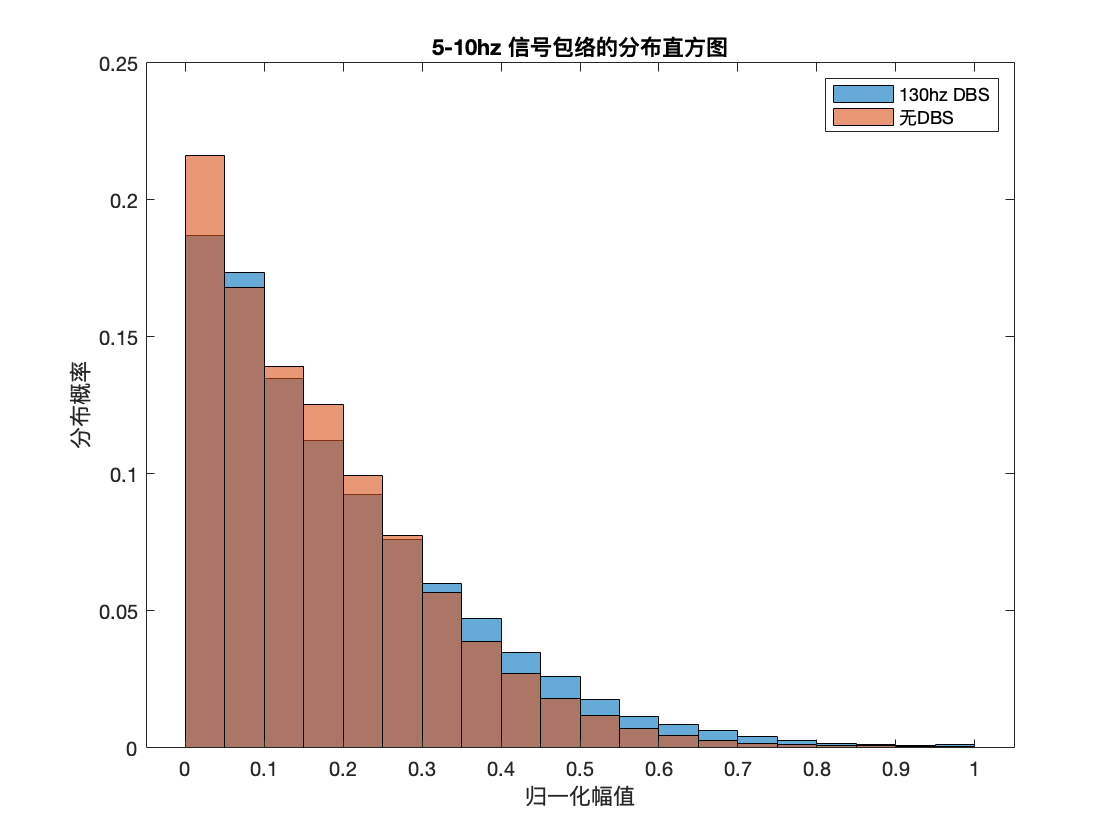

SignallistOff = [];
SignallistOn = [];
filename = '5-10Signal.png';
filetype = 'png';

for iside = 1:nside
    SignalON  = cell2mat(TotalSignalONDBS(iside));
    SignalOFF  = cell2mat(TotalSignalOFFDBS(iside));
    SignalOff = abs(hilbert(SignalOFF(5,:)));
    SignalOn = abs(hilbert(SignalON(5,:)));
    Signal = [SignalOff SignalOn];
    NormSignal = normalize(Signal,'range');
    NormSignalOff = NormSignal(1:length(SignalOff));
    NormSignalOn = NormSignal(length(SignalOff)+1:end);
    SignallistOff = [SignallistOff NormSignalOff];
    SignallistOn= [SignallistOn NormSignalOn];
end

figure;
edges = [0:0.05:1];
h1L = histogram(SignallistOff,edges,'Normalization','probability');
hold on
h2L = histogram(SignallistOn,edges,'Normalization','probability');
title('5-10hz 信号包络的分布直方图');
xlabel('归一化幅值');
ylabel('分布概率');
legend('130hz DBS','无DBS');
fig = gcf;
saveas(fig, filename, filetype);

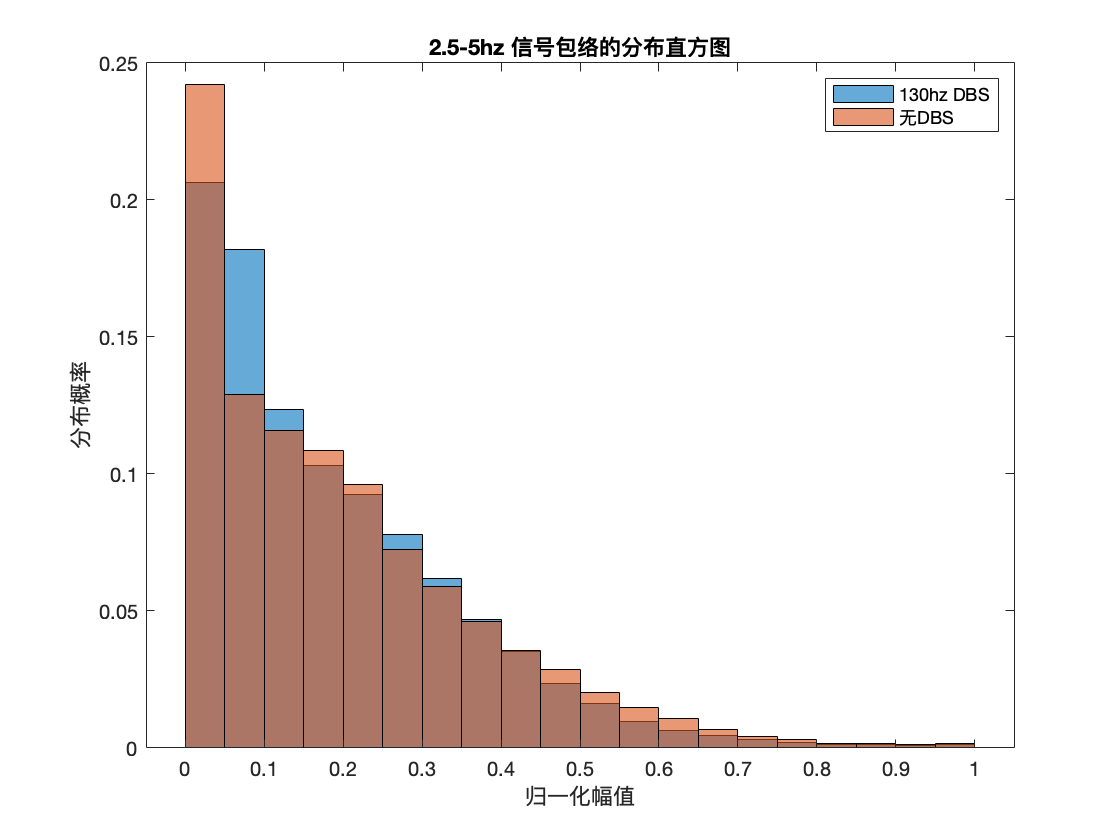

SignallistOff = [];
SignallistOn = [];
filename = '2.5-5Signal.png';
filetype = 'png';


for iside = 1:nside
    SignalON  = cell2mat(TotalSignalONDBS(iside));
    SignalOFF  = cell2mat(TotalSignalOFFDBS(iside));
    SignalOff = abs(hilbert(SignalOFF(6,:)));
    SignalOn = abs(hilbert(SignalON(6,:)));
    Signal = [SignalOff SignalOn];
    NormSignal = normalize(Signal,'range');
    NormSignalOff = NormSignal(1:length(SignalOff));
    NormSignalOn = NormSignal(length(SignalOff)+1:end);
    SignallistOff = [SignallistOff NormSignalOff];
    SignallistOn= [SignallistOn NormSignalOn];
end

figure;
edges = [0:0.05:1];
h1L = histogram(SignallistOff,edges,'Normalization','probability');
hold on
h2L = histogram(SignallistOn,edges,'Normalization','probability');
title('2.5-5hz 信号包络的分布直方图');
xlabel('归一化幅值');
ylabel('分布概率');
legend('130hz DBS','无DBS');
fig = gcf;
saveas(fig, filename, filetype);

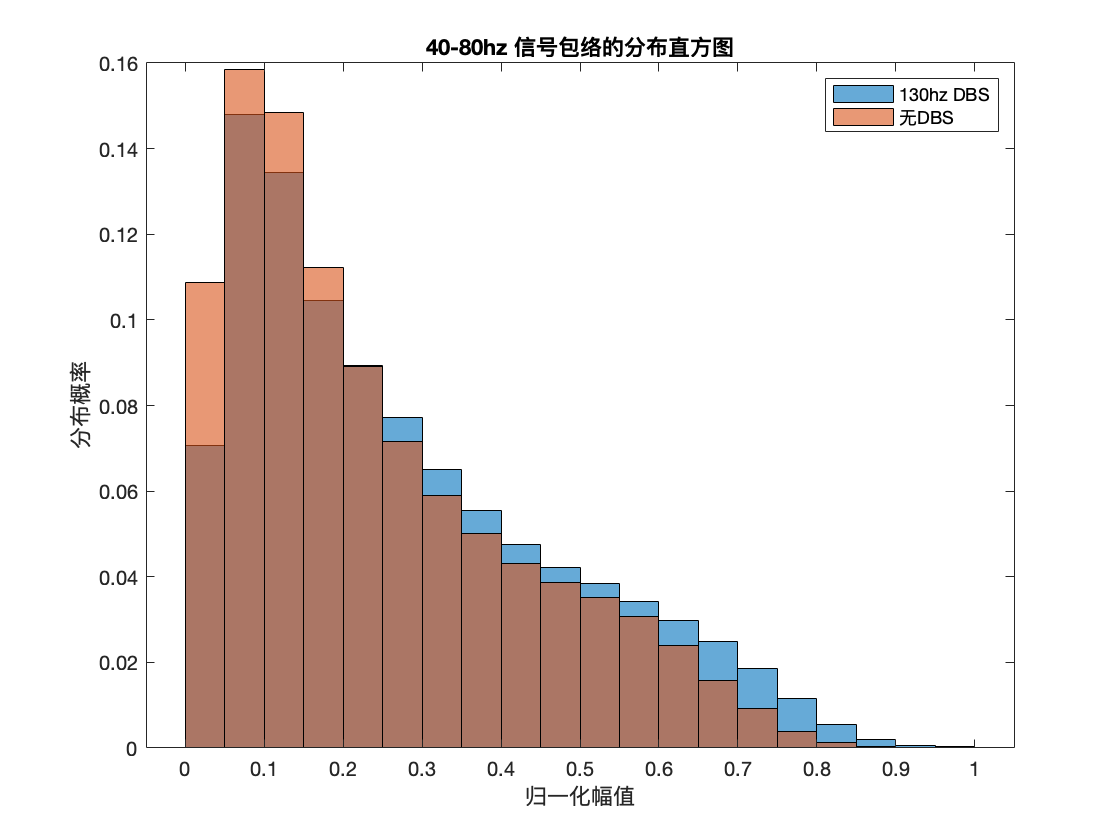

SignallistOff = [];
SignallistOn = [];
filename = '40-80Signal.png';
filetype = 'png';


for iside = 1:nside
    SignalON  = cell2mat(TotalSignalONDBS(iside));
    SignalOFF  = cell2mat(TotalSignalOFFDBS(iside));
    SignalOff = abs(hilbert(SignalOFF(2,:)));
    SignalOn = abs(hilbert(SignalON(2,:)));
    Signal = [SignalOff SignalOn];
    NormSignal = normalize(Signal,'range');
    NormSignalOff = NormSignal(1:length(SignalOff));
    NormSignalOn = NormSignal(length(SignalOff)+1:end);
    SignallistOff = [SignallistOff NormSignalOff];
    SignallistOn= [SignallistOn NormSignalOn];
end

figure;
edges = [0:0.05:1];
h1L = histogram(SignallistOff,edges,'Normalization','probability');
hold on
h2L = histogram(SignallistOn,edges,'Normalization','probability');
title('40-80hz 信号包络的分布直方图');
xlabel('归一化幅值');
ylabel('分布概率');
legend('130hz DBS','无DBS');
fig = gcf;
saveas(fig, filename, filetype);

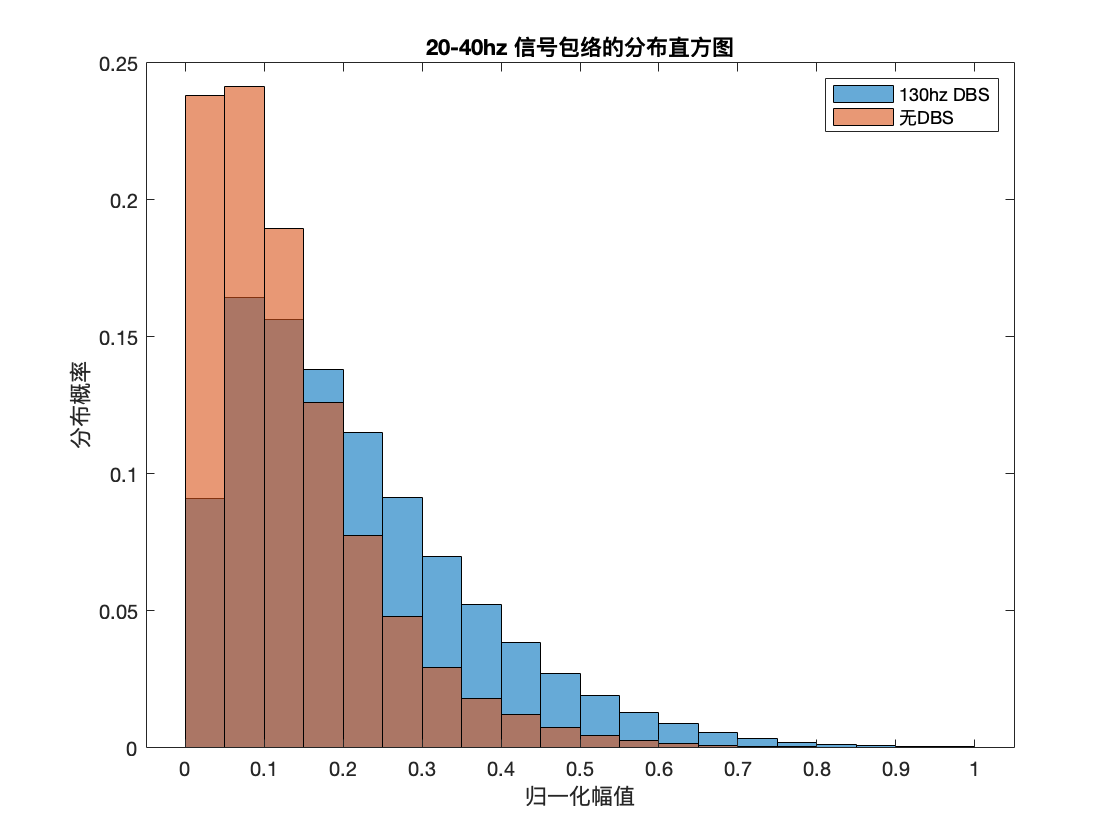

SignallistOff = [];
SignallistOn = [];
filename = '20-40Signal.png';
filetype = 'png';


for iside = 1:nside
    SignalON  = cell2mat(TotalSignalONDBS(iside));
    SignalOFF  = cell2mat(TotalSignalOFFDBS(iside));
    SignalOff = abs(hilbert(SignalOFF(3,:)));
    SignalOn = abs(hilbert(SignalON(3,:)));
    Signal = [SignalOff SignalOn];
    NormSignal = normalize(Signal,'range');
    NormSignalOff = NormSignal(1:length(SignalOff));
    NormSignalOn = NormSignal(length(SignalOff)+1:end);
    SignallistOff = [SignallistOff NormSignalOff];
    SignallistOn= [SignallistOn NormSignalOn];
end

figure;
edges = [0:0.05:1];
h1L = histogram(SignallistOff,edges,'Normalization','probability');
hold on
h2L = histogram(SignallistOn,edges,'Normalization','probability');
title('20-40hz 信号包络的分布直方图');
xlabel('归一化幅值');
ylabel('分布概率');
legend('130hz DBS','无DBS');
fig = gcf;
saveas(fig, filename, filetype);

%}